clear;clc;

## 读取数据

load("PointOctahedron.mat")
P_bound1 = top_face_transformed(10,:);
P_bound2 = bottom_face_transformed(20,:);
planes = planes';

[PlaneParaOut,TrianglePoints] = planefit8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2);


## 验证

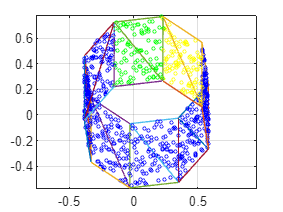

figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(:,1),side_faces_transformed1(:,2),side_faces_transformed1(:,3),5,'yellow')
scatter3(side_faces_transformed2(:,1),side_faces_transformed2(:,2),side_faces_transformed2(:,3),5,'green')
scatter3(side_faces_transformed3(:,1),side_faces_transformed3(:,2),side_faces_transformed3(:,3),5,'blue')
scatter3(side_faces_transformed4(:,1),side_faces_transformed4(:,2),side_faces_transformed4(:,3),5,'blue')
scatter3(side_faces_transformed5(:,1),side_faces_transformed5(:,2),side_faces_transformed5(:,3),5,'blue')
scatter3(side_faces_transformed6(:,1),side_faces_transformed6(:,2),side_faces_transformed6(:,3),5,'blue')
scatter3(side_faces_transformed7(:,1),side_faces_transformed7(:,2),side_faces_transformed7(:,3),5,'blue')
scatter3(side_faces_transformed8(:,1),side_faces_transformed8(:,2),side_faces_transformed8(:,3),5,'blue')
for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end